# 02D. Stability

## Mingyang Lu

## 01/07/2024

### Stability of steady states

Consider $\frac{dX}{dt}=g-kX$. We first plot the first and second terms of the derivative function separately.

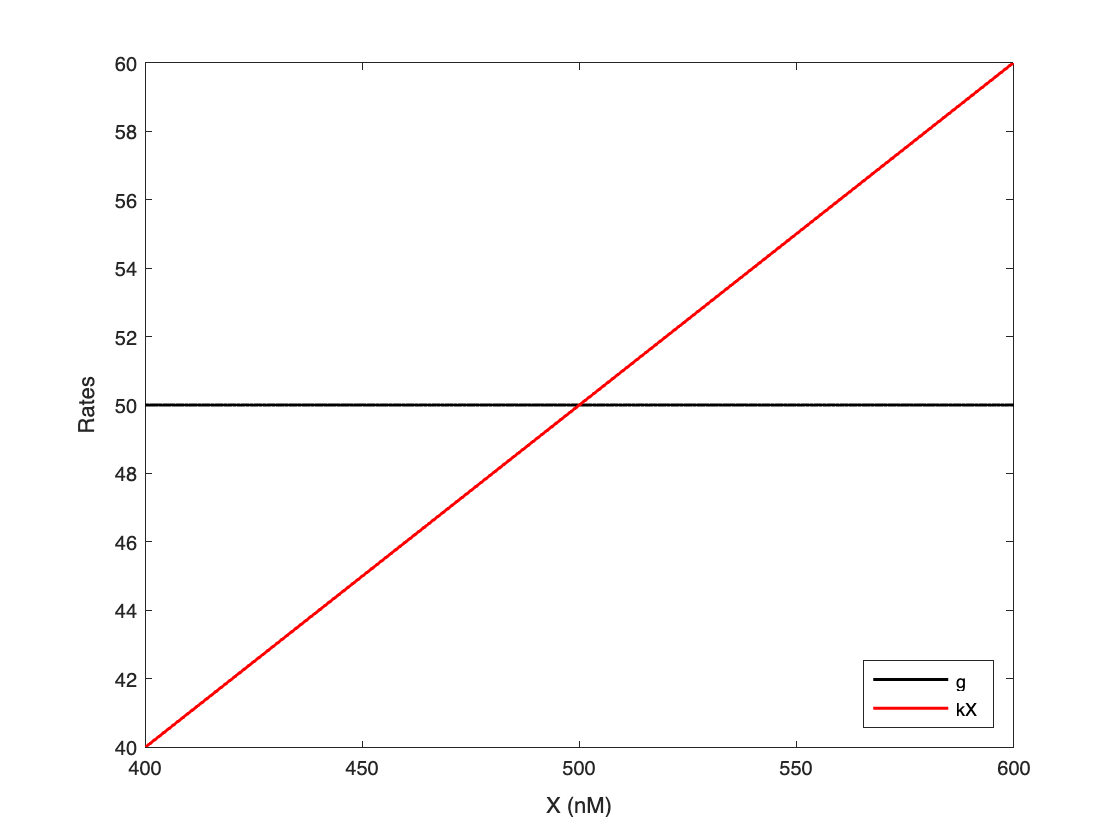

% Define parameters
g = 50;
k = 0.1;

% All X values to be sampled
X_all = 400:1:601;

% Plot the first term g
plot(X_all, ones(size(X_all)) * g, 'k', 'LineWidth', 1.5, 'DisplayName', 'g');
hold on;

% Add the second term kX
plot(X_all, k * X_all, 'r', 'LineWidth', 1.5, 'DisplayName', 'kX');

% Set axis labels and limits
xlabel('X (nM)');
ylabel('Rates');
xlim([400, 600]);
ylim([40, 60]);

% Add legend
legend('Location', 'southeast');
hold off;

The intersect of the two curves represents the steady state. It's a stable steady state, when $\frac{df(X)}{dX}<0$.

Now, let us consider the circuit with a self-inhibiting gene, whose dynamics is governed by


$$\frac{dX}{dt}=g(X)-kX$$


,where $g(X)=g_0 +g_1 H^{inh} (X)$. $H^{inh} (X)$ is the inhibitory Hill function with expression

$H^{inh} (X)\equiv \frac{1}{1+(X/X_{th} )^{n_X } }$.

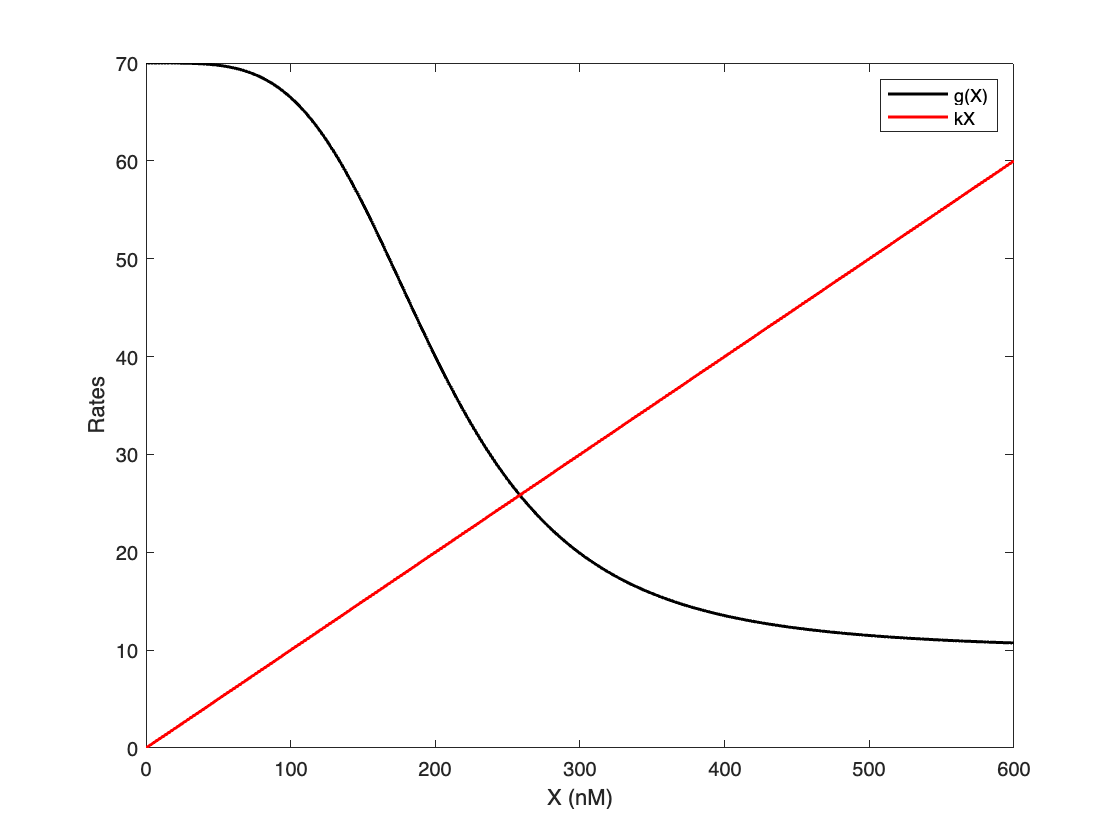

% Define parameters
g_0 = 10;
g_1 = 60;
k = 0.1;
X_th = 200;
n = 4;

% Inhibitory Hill function
% X_th: Hill threshold, n: Hill coefficient
hill_inh = @(X) 1 ./ (1 + (X / X_th).^n);

% All X values to be sampled
X_all = 0:1:600;

% Plot the first term g(X)
plot(X_all, g_0 + g_1 * hill_inh(X_all), 'k', 'LineWidth', 1.5, 'DisplayName', 'g(X)');
hold on;

% Plot the second term kX
plot(X_all, k * X_all, 'r', 'LineWidth', 1.5, 'DisplayName', 'kX');

% Set axis labels and limits
xlabel('X (nM)');
ylabel('Rates');
xlim([0, 600]);
ylim([0, 70]);

% Add legend
legend('Location', 'northeast');
hold off;

Let us also compute $\frac{df(X)}{dX}$. Note that we use vector operations for high efficiency.

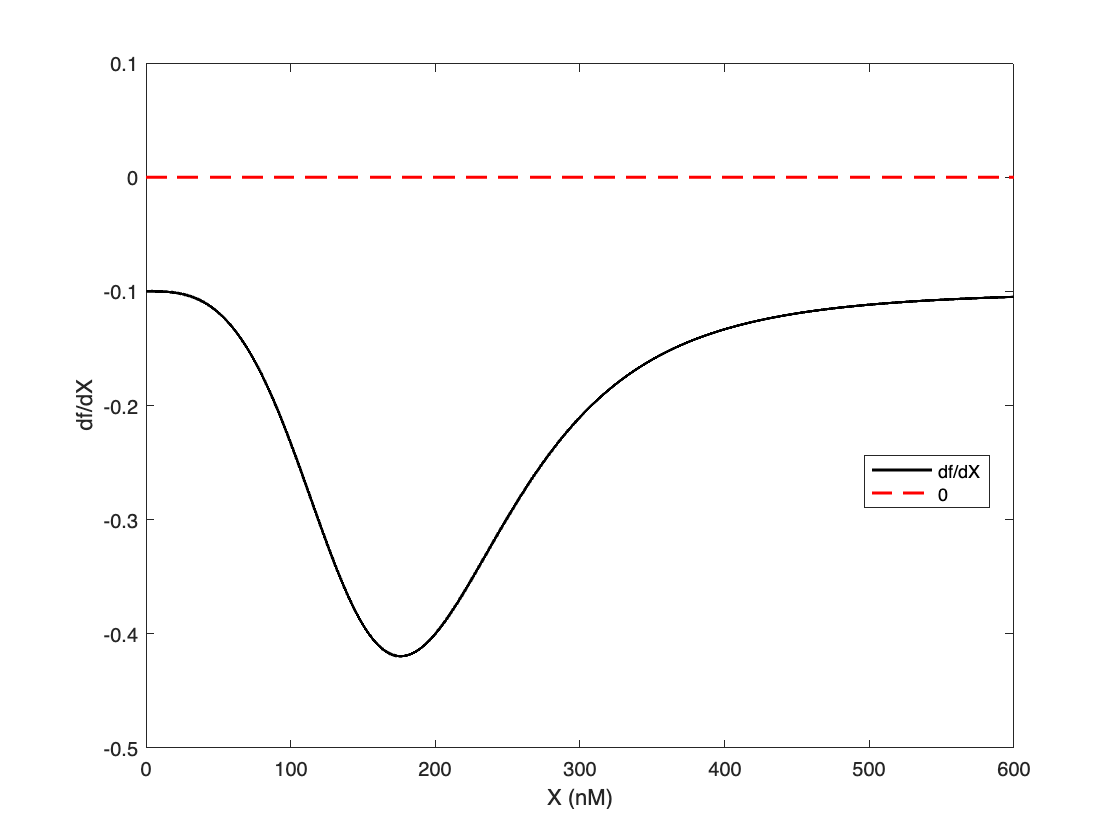

% All X values to be sampled
X_all = 0:0.1:600;

% Calculate df(X)/dt
dt = 0.1;
dfdX = cal_dfdx(X_all, dt, @f_1g_self_inh, 10, 60, 200, 4, 0.1);

% Plot df(X)/dX
plot(X_all, dfdX, 'k', 'LineWidth', 1.5, 'DisplayName', 'df/dX');
hold on;

% Add horizontal line at y=0
plot([0, 600], [0, 0], '--r', 'LineWidth', 1.5, 'DisplayName', '0');

% Set axis labels and limits
xlabel('X (nM)');
ylabel('df/dX');
xlim([0, 600]);
ylim([-0.5, 0.1]);

% Add legend
legend('Location', 'Best');
hold off;

In this case, $\frac{df(X)}{dX} < 0$ at the steady state X (around 250 nM). Thus, the steady state is stable.

### Multi-stability

The third example is the circuit with a self-activating gene, whose dynamics is governed by


$$\frac{dX}{dt}=g(X)-kX$$


,where $g(X)=g_0 +g_1 H^{ex} (X)$. $H^{ex} (X)$ is the excitatory Hill function with expression


$$H^{ex} (X)\equiv \frac{(X/X_{th} )^{n_X } }{1+(X/X_{th} )^{n_X } }$$


Again, we plot $g(X)$ and $kX$. In the plot below, we vary the value of $k$ and fix the rest of the parameters. 

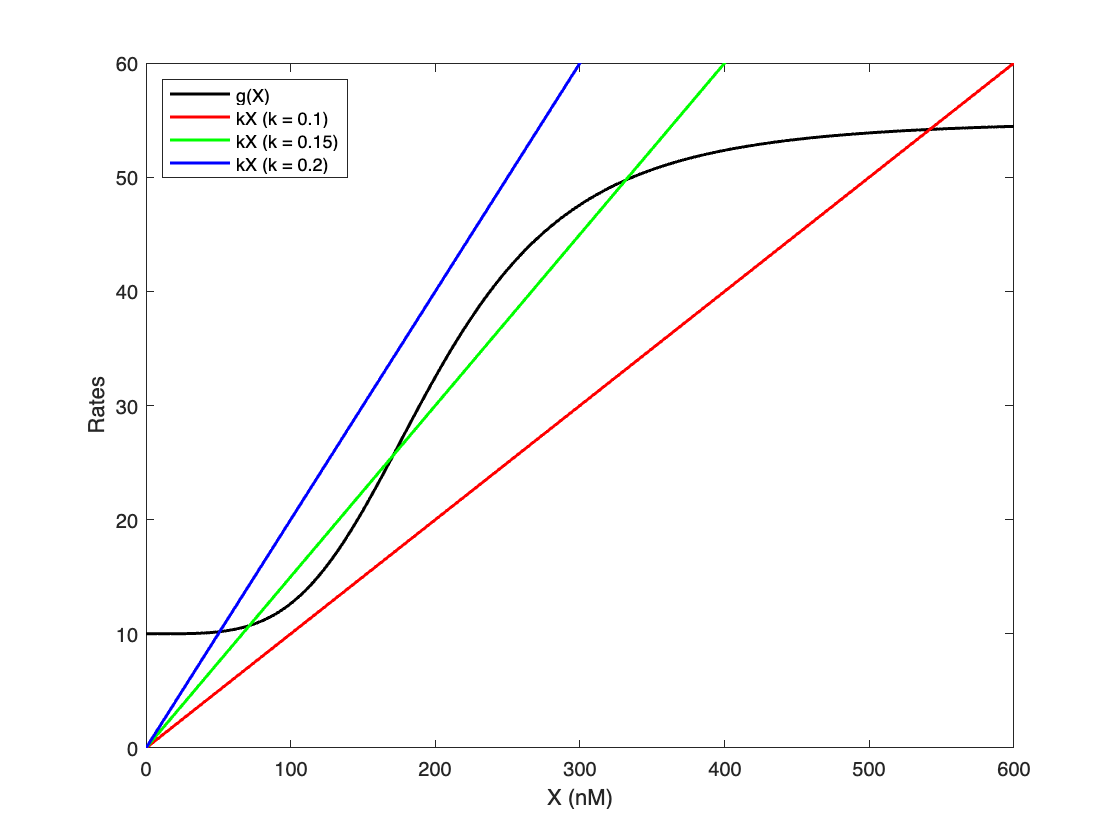

% Define parameters
g0 = 10;
g1 = 45;
X0 = 200;
n = 4;

% Excitatory Hill function
% X_th: Hill threshold, n: Hill coefficient
hill_ex = @(X, X_th, n) (X / X_th).^n ./ (1 + (X / X_th).^n);

% All X values to be sampled
X_all = 0:1:600;

% Plot the first term g(X)
plot(X_all, g0 + g1 * hill_ex(X_all, X0, n), 'k', 'LineWidth', 1.5, 'DisplayName', 'g(X)');
hold on;

% Plot the second term kX for different values of k
plot(X_all, 0.1 * X_all, 'r', 'LineWidth', 1.5, 'DisplayName', 'kX (k = 0.1)');
plot(X_all, 0.15 * X_all, 'g', 'LineWidth', 1.5, 'DisplayName', 'kX (k = 0.15)');
plot(X_all, 0.2 * X_all, 'b', 'LineWidth', 1.5, 'DisplayName', 'kX (k = 0.2)');

% Set axis labels and limits
xlabel('X (nM)');
ylabel('Rates');
xlim([0, 600]);
ylim([0, 60]);

% Add legend
legend('Location', 'northwest');
hold off;

When $k=0\ldotp 1$ or $k=0\ldotp 2$, the circuit has only one steady state. 

When $k=0\ldotp 15$, the circuit has three steady states. Two of these steady states are stable, and the other one is unstable. This is called bistability. We can simulate the ODE with different initial conditions to see that time trajectories converge to two steady states.

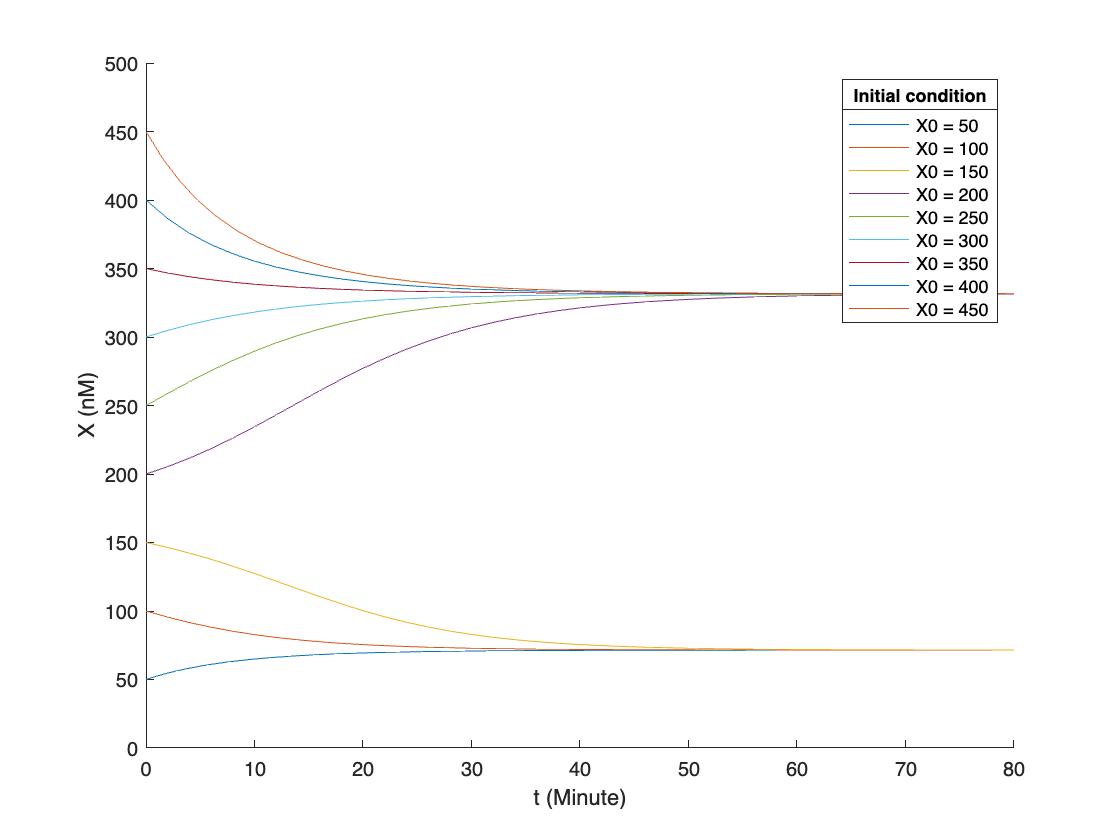

% Define parameters
g0 = 10;
g1 = 45;
X_th = 200;
n = 4;
k = 0.15;

% Time sequence for which output is needed
t_all = 0:0.1:80;

% All initial conditions, each leads to a different simulation
X0_all = 50:50:450;

% Initialize plotting
figure;
xlabel('t (Minute)');
ylabel('X (nM)');
xlim([0, 80]);
ylim([0, 500]);

% ODE simulation per initial condition
legend_text = cell(1, numel(X0_all));
hold on;
for i = 1:numel(X0_all)
    X0 = X0_all(i);
    [t, y] = ode45(@(t, y) dy_deSolve_1g_self_act(t, y, g0, g1, X_th, n, k), [0, 80], X0);
    plot(t, y, 'DisplayName', ['X0 = ', num2str(X0)]);
    
    legend_text{i} = ['X0 = ', num2str(X0)];
end

% Add legend
legend('Location', 'northeast');
lgd = legend;
lgd.Title.String = 'Initial condition';
hold off;

Again, we can also learn the stability of steady states from the $\frac{df(X)}{dX}$ curve.

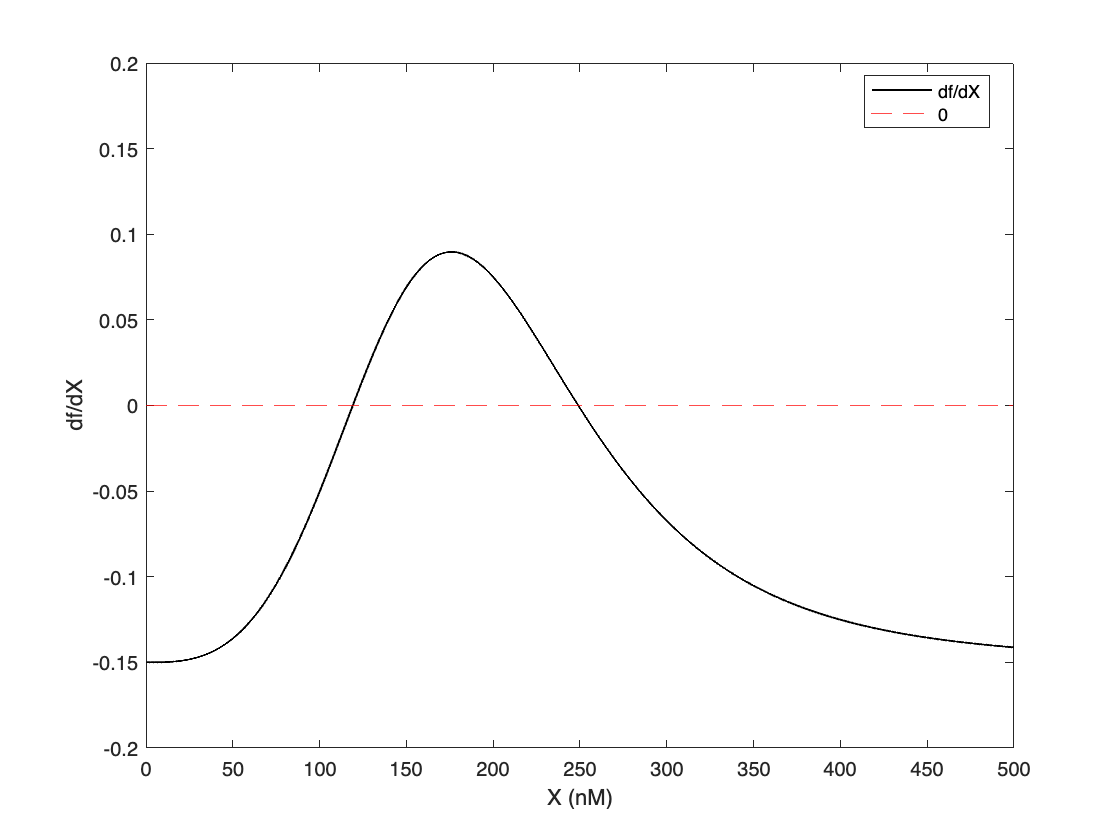

% Define parameters
g0 = 10;
g1 = 45;
X_th = 200;
n = 4;
k = 0.15;

% All X values to be sampled
X_all = 0:0.1:500;

% Calculate df(X)/dt
dt = 0.1;
dfdX = cal_dfdx(X_all, dt, @(X) f_1g_self_act(X, g0, g1, X_th, n, k));

% Plot df(X)/dX
figure;
plot(X_all, dfdX, 'k', 'LineWidth', 1, 'DisplayName', 'df/dX');
hold on;
yline(0, '--', 'Color', 'red', 'DisplayName', '0');

% Set axis labels and limits
xlabel('X (nM)');
ylabel('df/dX');
xlim([0, 500]);
ylim([-0.2, 0.2]);

% Add legend
legend('show', 'Location', 'best');
hold off;

### Effective potential

For an ODE $\frac{dX}{dt}=f(X)$, the potential function can be defined as


$$U(X)=-\int_{X_0 }^X f(x)dx+U(X_0 )$$


We set $U(X_0 =0)=0$. A common numerical method to integrate a function is by the trapezoidal rule. We got

$U(X+\Delta x)=U(X)-\frac{f(X)+f(X+\Delta x)}{2}\Delta x$.

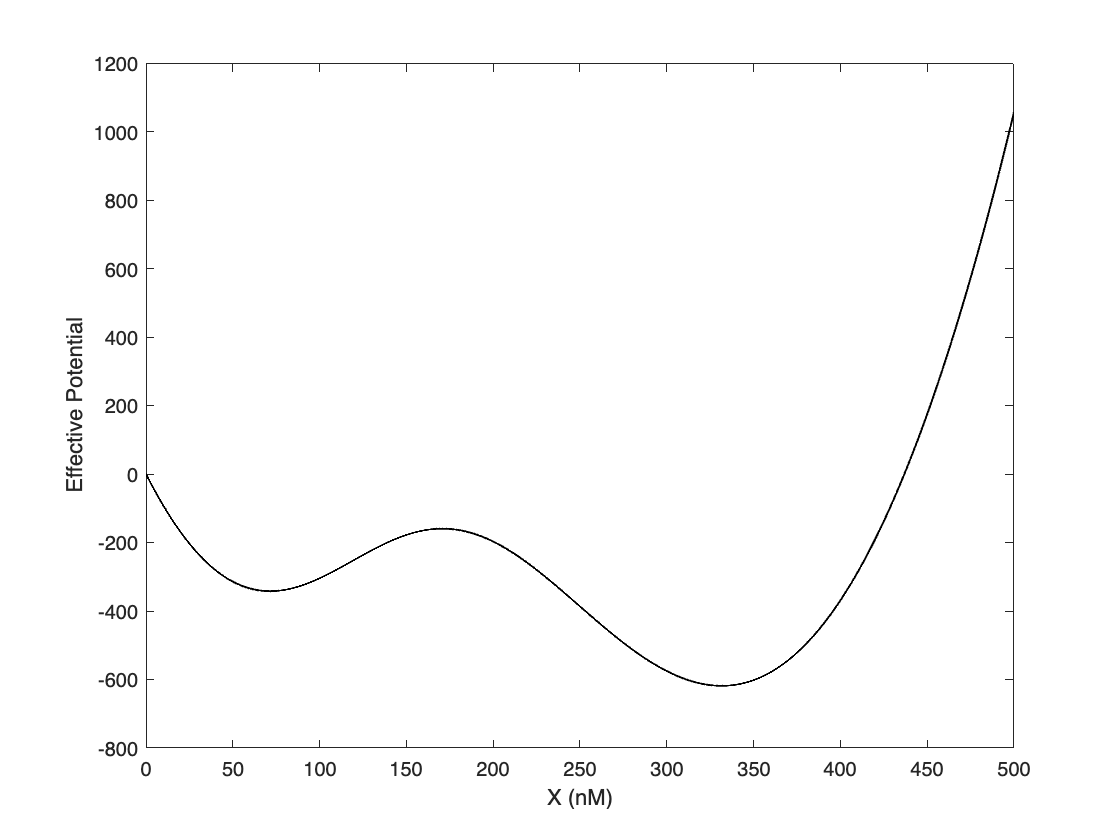

% Calculate effective potential
results_1 = cal_int(0, 500, 0.1, @(X) f_1g_self_act(X, g0, g1, X_th, n, k));

% Plot effective potential
figure;
plot(results_1(:, 1), results_1(:, 2), 'k', 'LineWidth', 1);
xlabel('X (nM)');
ylabel('Effective Potential');
xlim([0, 500]);

Same numerical integration, but this time with vectorization.

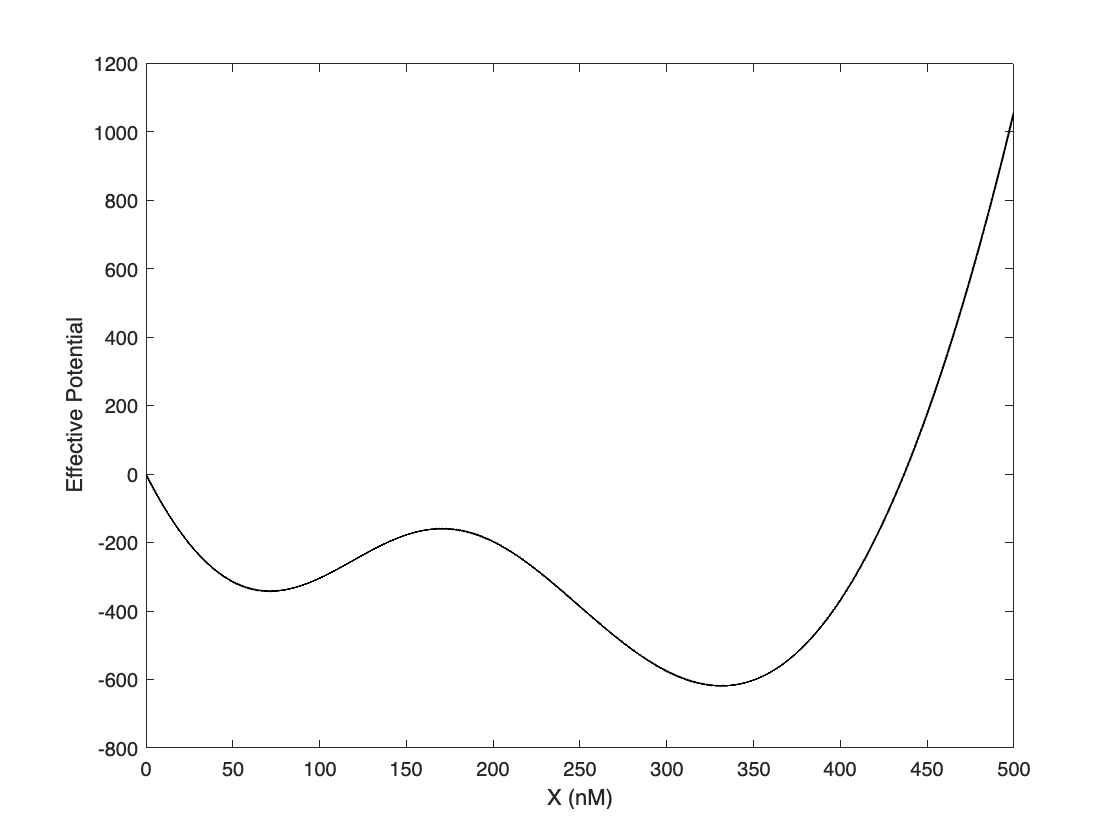

% Calculate effective potential with vectorized approach
results_2 = cal_int_vector(0, 500, 0.1, @(X) f_1g_self_act(X, g0, g1, X_th, n, k));

% Plot effective potential
figure;
plot(results_2(:, 1), results_2(:, 2), 'k', 'LineWidth', 1);
xlabel('X (nM)');
ylabel('Effective Potential');
xlim([0, 500]);

Benchmarking:

% Benchmarking cal_int
tic;
cal_int(0, 500, 0.1, @f_1g_self_act, 10, 45, 200, 4, 0.15);
toc;

Elapsed time is 0.005923 seconds.



% Benchmarking cal_int_vector
tic;
cal_int_vector(0, 500, 0.1, @f_1g_self_act, 10, 45, 200, 4, 0.15);
toc;

Elapsed time is 0.002737 seconds.


Finally, we show the effective potential for $k=0.2{\textrm{Minute}}^{-1}$.

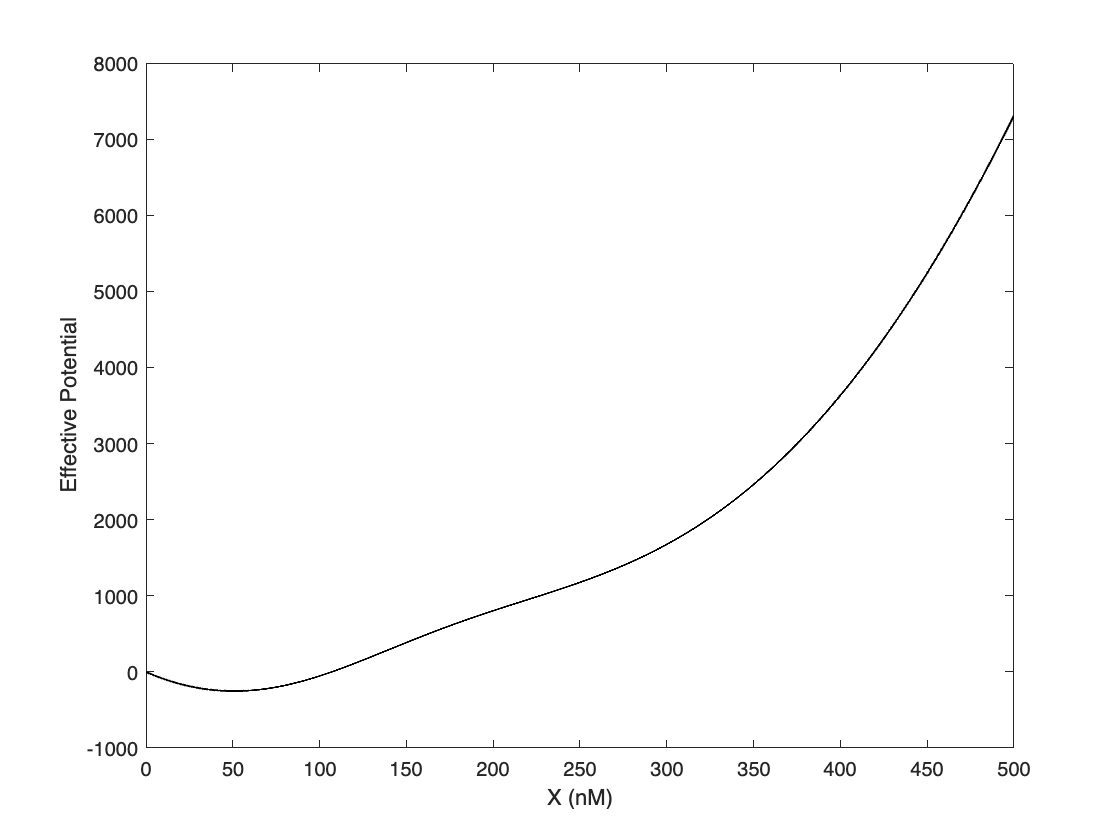

% Calculate effective potential with vectorized approach
k = 0.2;
results_2 = cal_int_vector(0, 500, 0.1, @(X) f_1g_self_act(X, g0, g1, X_th, n, k));

% Plot effective potential
figure;
plot(results_2(:, 1), results_2(:, 2), 'k', 'LineWidth', 1);
xlabel('X (nM)');
ylabel('Effective Potential');
xlim([0, 500]);

And the effective potential for $k=0\ldotp 1{\textrm{Minute}}^{-1}$.

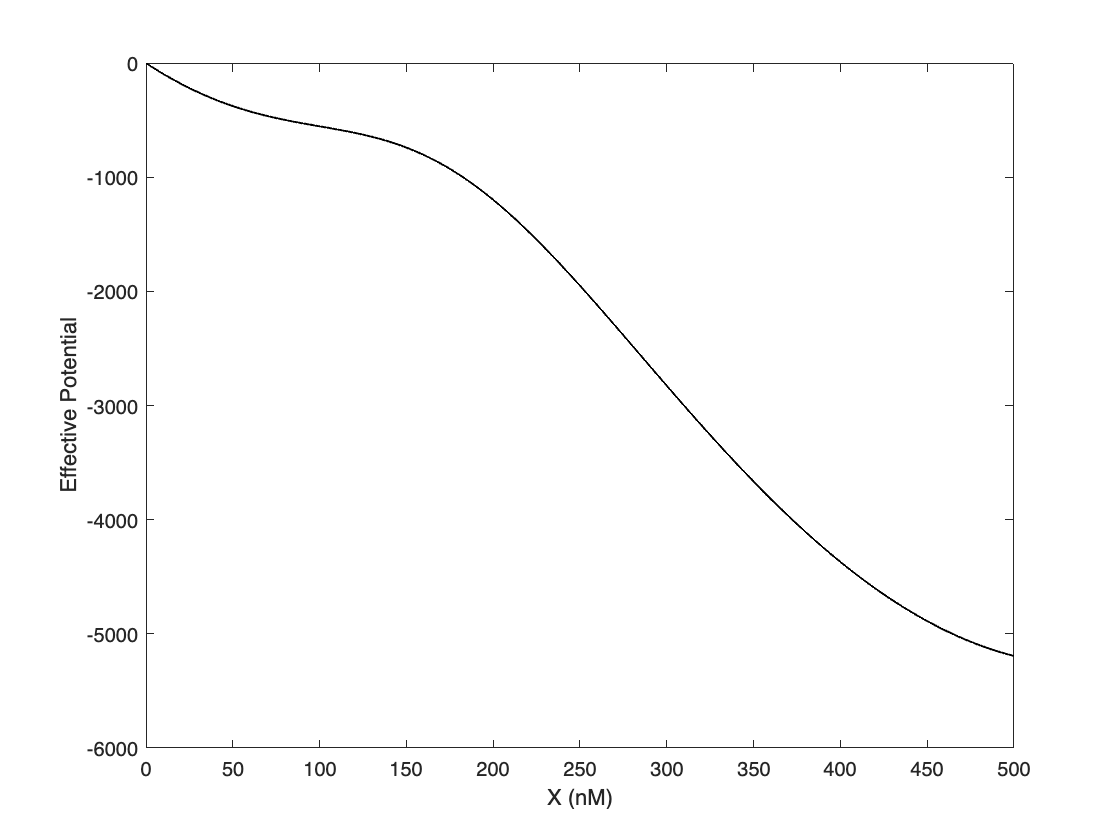

% Calculate effective potential with vectorized approach
k = 0.1;
results_2 = cal_int_vector(0, 500, 0.1, @(X) f_1g_self_act(X, g0, g1, X_th, n, k));

% Plot effective potential
figure;
plot(results_2(:, 1), results_2(:, 2), 'k', 'LineWidth', 1);
xlabel('X (nM)');
ylabel('Effective Potential');
xlim([0, 500]);

### Define MATLAB functions

1. Caculate f(x) for the case of one gene with self-inhibition.

function result = f_1g_self_inh(X, g0, g1, X_th, n, k)
    hill_inh = 1 ./ (1 + (X / X_th).^n);
    result = g0 + g1 * hill_inh - k * X;
end

2. Calculate df(X)/dt.

function dfdX = cal_dfdx(X_all, dt, derivs, varargin)
    % X_all is a vector of all X values to be sampled
    % derivs takes the name of the derivatives function
    % varargin to take model parameters

    % f(X) for all X values in a vector
    f_all = derivs(X_all, varargin{:})';

    % f(X+dx), achieved by shifting the vector by one to the left
    f_all_shift_by_plus_one = [f_all(2:end); NaN];
    % f(X-dx), achieved by shifting the vector by one to the right
    f_all_shift_by_minus_one = [NaN; f_all(1:end-1)];

    % df/dX = (f(X+dx) - f(X-dx))/2/dt
    dfdX = (f_all_shift_by_plus_one - f_all_shift_by_minus_one) / (2 * dt);
end

3. Modified derivative function for MATLAB ode solver

function dydt = dy_deSolve_1g_self_act(t, y, g0, g1, X_th, n, k)
    hill_ex = (y / X_th).^n ./ (1 + (y / X_th).^n);
    dydt = g0 + g1 * hill_ex - k * y;
end

4. Caculate f(x) for the case of one gene with self-activation.

function result = f_1g_self_act(X, g0, g1, X_th, n, k)
    hill_inh = 1 ./ (1 + (X / X_th).^n);
    result = g0 + g1 * (1-hill_inh) - k * X;
end

5. Integrate f(X) with the trapezoidal rule

function results = cal_int(Xmin, Xmax, dX, f, varargin)
    % Xmin: minimum X values
    % Xmax: maximum X values
    % dX: X step size
    % varargin to pass all model parameters
    
    X_all = Xmin:dX:Xmax;
    nX = length(X_all);
    
    % Initialize a vector of potential U
    U_all = zeros(1, nX);

    for i = 1:nX-1
        X = X_all(i);
        U_all(i + 1) = U_all(i) - (f(X, varargin{:}) + f(X + dX, varargin{:})) / 2 * dX;
    end

    results = [X_all' U_all'];
end

6. Integrate f(X) with the vectorized approach

function results = cal_int_vector(Xmin, Xmax, dX, f, varargin)
    % Xmin: minimum X values
    % Xmax: maximum X values
    % dX: X step size
    % varargin to pass all model parameters
    
    X_all = Xmin:dX:Xmax;
    f_all = f(X_all, varargin{:});  % generate all f(X)
    % another array containing f(X+dx), except for the last point
    f_all_shift_by_plus_one = [f_all(2:end), NaN];  
    f_all = (f_all + f_all_shift_by_plus_one) * dX / 2;  % each integrated part
    U_all = -cumsum(f_all);
    results = [X_all' U_all'];
end